## Ouverture de l'image

avec un .jpg on n'a pas besoin des maps de couleurs colormap pcq les infos sont deja enregistrées

[im , map] = imread("TP_TSI/lac-blanc.jpg");

size(im)

ans =          683        1000           3


size(map)

ans =      0     0


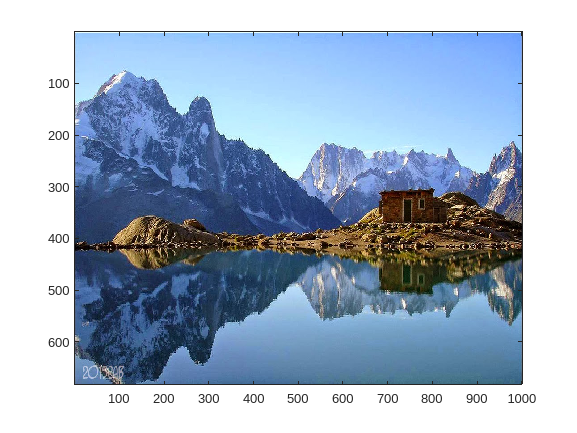


figure(1)
image(im);

Le terme '3' correspond aux trois couleurs (RGB). 

Si on veut modifier la compante rouge

On note que

- 1 correspond au plan rouge

- 2 vert

- 3 bleu    

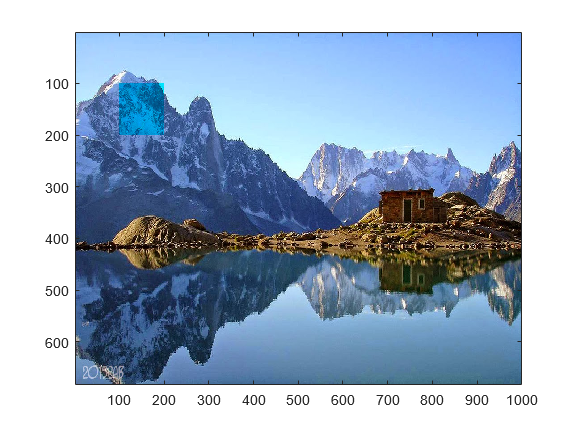

im(100:200,100:200,1) = 0;
figure(2)
image(im);

% on met la composante rouge a zero pour les lignes et colonnes 100 à 200
% sinon im(100:200,100:200,2) = 0 pour virer la composante verte

La on va se remettre en noir et blanc pour faire varier la luminosité (ndg : niveaux de gris)

ndg = im(:,:,1) * 0.3; % contient ensemble intensites lumineuses (ensemble des composantes rouges pondérées à 0.3)
ndg = ndg + 0.59*im(:,:,2) + 0.11*im(:,:,3); % on aura l'impression que le vert est 6* plus brillant que le bleu

% palette de niveaux de gris
gris = [0:255]'/255 * [1 1 1]

gris =          0         0         0
    0.0039    0.0039    0.0039
    0.0078    0.0078    0.0078
    0.0118    0.0118    0.0118
    0.0157    0.0157    0.0157
    0.0196    0.0196    0.0196
    0.0235    0.0235    0.0235
    0.0275    0.0275    0.0275
    0.0314    0.0314    0.0314
    0.0353    0.0353    0.0353


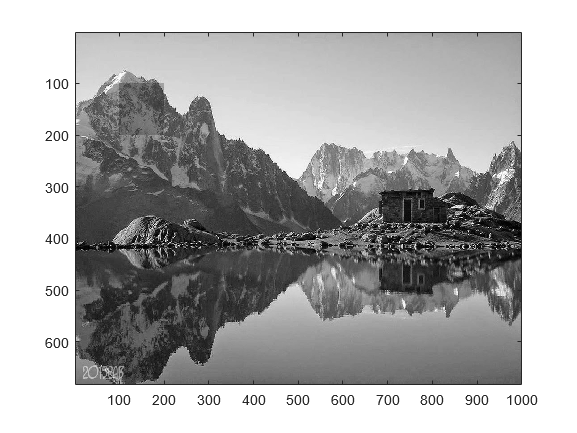

figure(3);
image(ndg)
colormap(gris)

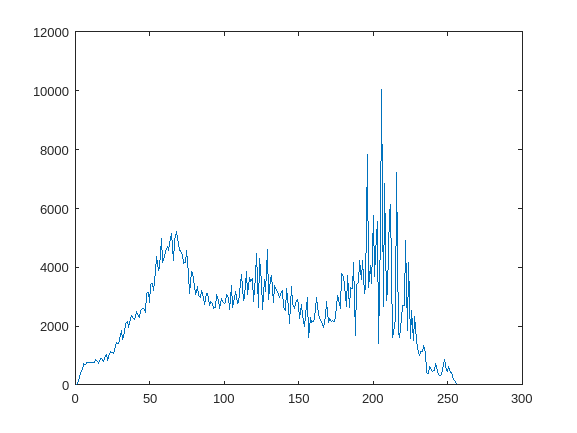


h = histo(ndg);
figure(4)
plot(h);

% Erreur obtenue, c'est normal
% ça dépend des images


L'erreur qu'on obtient est due au fait qu'on a des valeur à 0 donc de pixel qui correspondent à du noir complet, donc on passe pas dans la situation ou on essaie d'indexer la valeur de h à 0. 

Les index de matlab commencent à 1. Pour régler notre problème de pixel à 0, on rajoute 1 à l'interieur des parentheses de h (pour shift les indices).

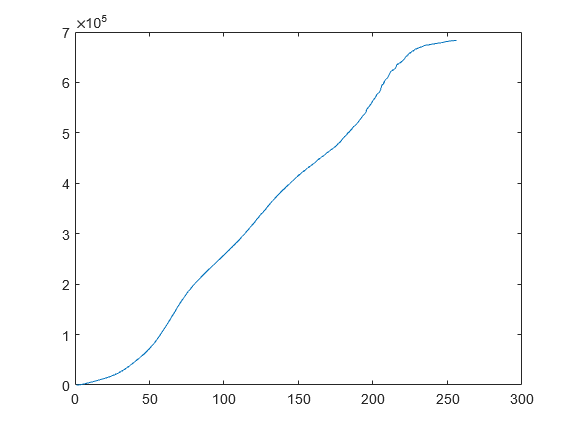

hcum = histocum(ndg);
figure(5)
plot(hcum);

Plus on avance dans les valeurs, plus on ajoute les valeurs qui précèdent, donc c'est croissant. Ces informations sont pas bcp plus pertinentes que celles de l'histogramme classique.

## Grenier

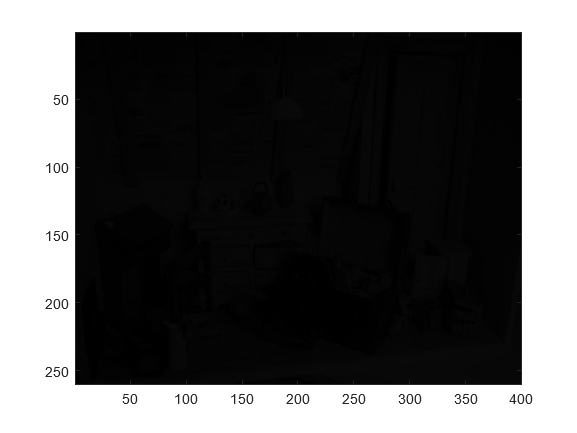

[grenier , map] = imread("TP_TSI/grenier.png");

figure(6)
image(grenier);
colormap(gris)

*Ici on ouvre un PNG, donc l'image est en noir et blanc. Le paramètre map doit forcément stocker les informations de couleurs.*

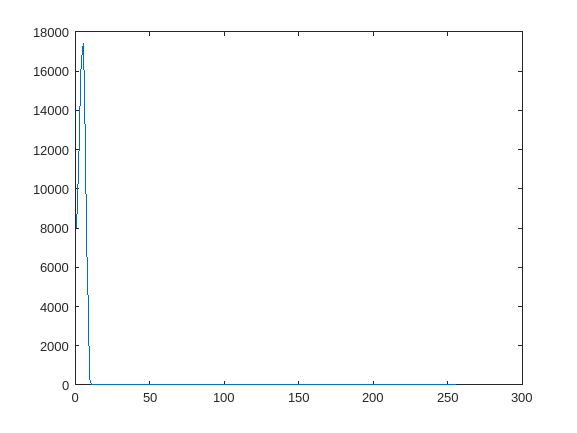

h = histo(grenier);
figure(7)
plot(h);

Tout n'est pas complètement noir (on a quand meme des valeurs non nulles donc on a juste des mini variations)

On va donc faire un recadrage pour ameliorer ca (on prend min et max et on etend ca sur l'ensemble des valeurs de 0 à 255).

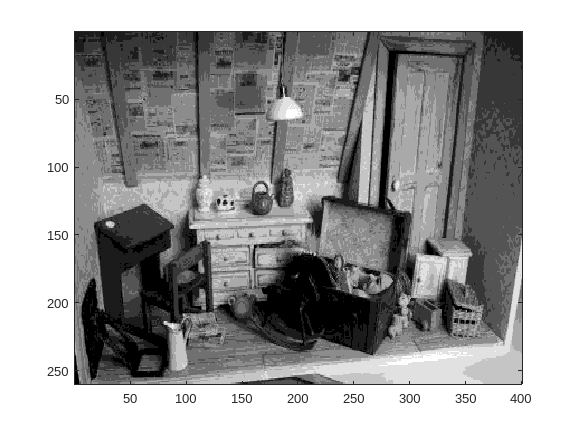

% recadrage
grenier = double(grenier);
mini = min(min(grenier)); % deux fois sinon on a un vecteur colonne
maxi = max(max(grenier)); % same
recadr = (grenier - mini)/(maxi-mini)*255; % on a plus que des valeurs entre 0 et 255 normalement

figure(8)
image(recadr);
colormap(gris)

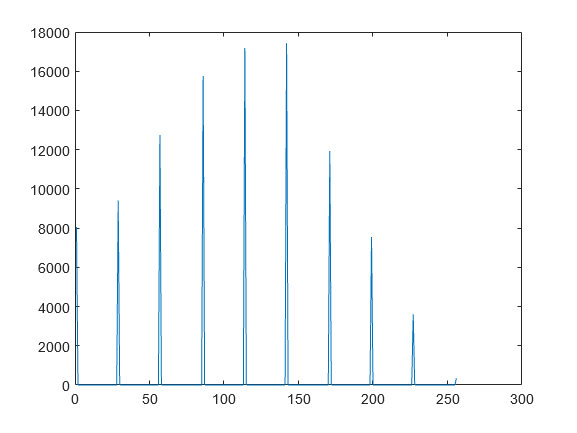


h = histo(floor(recadr)); % on a des virgules dans recadr, donc ya une erreur (we need int) - on round les values
figure(9)
plot(h);

On a toutes les valeurs qui sont étalées entre 0 et 256 now, image plus contrastée, meme si le dégradé entre deux valeurs de niveaux de gris a un gros gap.

## Contraste

K = 3 % pour augmenter la dynamique

K = 3

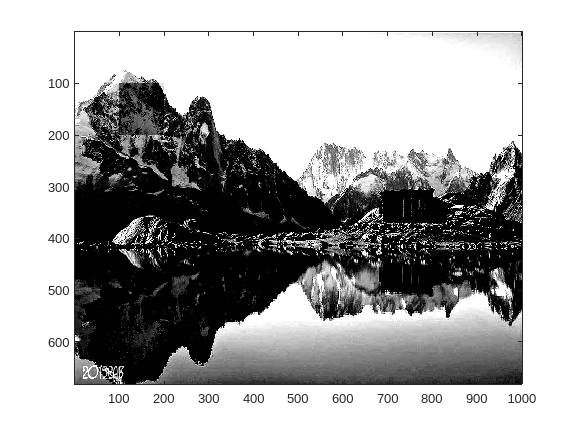

ndg = double(ndg); % pour avoir une meilleure image
moy = mean(mean(ndg));
contrast = K*(ndg-moy) + moy; % a quelle distance on est de la valeur moyenne + moyenne + ponderation pour bien voir la diff
figure(10)
image(contrast);
colormap(gris)

On obtient qqch de beaucoup plus contrasté (on peut faire varier K). La valeur de la moyenne sert de pivot.

On va transformer ca en histo plat (tous les niveaux de gris sont représentés en nombre équivalent de pixels). Les zones claires / sombres / intermediaires ne seront pas plus représentées que les autres. On va se débrouiller pour avoir qqch d'homogène, de mieux réparti. On pourra pas avoir qqch de parfaitement plat, mais on aura de la discrétisation (comme quand on a tiré sur les valeurs pour le grenier). Pour cela, on utilise qqch lié a histocum. Il augmente la dynamique de facon importante dans les endroits ou ya bcp de représentants et la comprimer dans les autres endroits. On va utiliser une transformation qui s'appelle XXX, mais il faut d'abord ramener le carré de l'histogramme à un carré d'ordonnées et d'abscisses allant de 0 à 255. On va diviser tout ca pour avoir la bonne échelle.

## Histogramme plat : égalisation

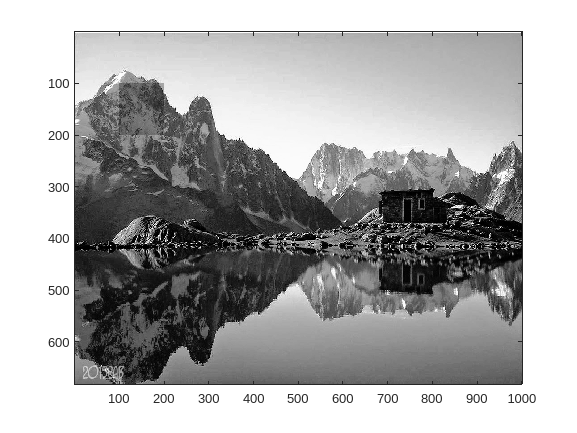

hcum = histocum(ndg);

NL = size(ndg,1); % nb de lignes
NC = size(ndg,2); % nb de colonnes
egalis = zeros(NL,NC);
hcum = hcum/(NL*NC)*255; % on ramene sur 1 puis sur 255

for L=1:NL
    for C=1:NC
        egalis(L,C) = hcum(floor(ndg(L,C)) + 1); % on recupere la valeur de l'histogramme du pixel courant
    end
end
figure(11)
image(egalis);
colormap(gris)

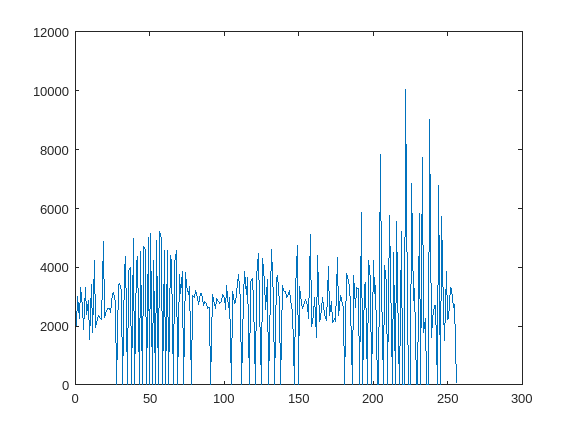


h = histo(floor(egalis));
figure(12)
plot(h);

Augmentation de la dynamique dans les zones très représentées. On comprime pour augmenter la densité dans les zones peu représentées. Tout ce qu'on a gagné sur la zone faiblement représentée est récupéré pour allonger les zones très représentées.

## Modifications des pixels de l'image en fonction du voisinage

Petite modif des intensités lumineuses en fonction du contexte. Convolution : modifs locales qui se font de façon linéaire. Les bords sont exclus. C'est intéressant quand on reste sur des masques 3x3, 5x5 mais pas pour des masques plus grands. Impairs pour avoir des centres  clairement définis

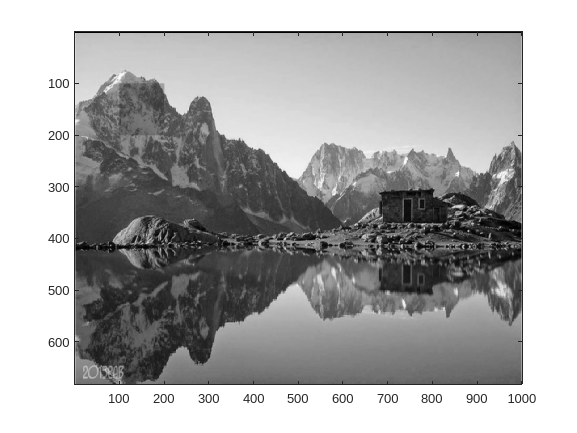

% convolution
masque = [1 1 1 ; 1 1 1 ; 1 1 1];
W = 9; % ensemble des coefs du masque, coef de pondération (3*3)
NL = size(ndg,1); % nb de lignes
NC = size(ndg,2); % nb de colonnes
conv = zeros(NL,NC);

for L=2:NL-1
    for C=2:NC-1
        conv(L,C) = sum(sum(masque.*ndg(L-1:L+1,C-1:C+1))) / W;
        % intégrations de la partie de ndg qui se trouve sous le masque 
        % pareil pour le sum(sum()) pour avoir la somme complète et pas un
        % vecteur colonne uniquement des sommes des pixels
        % mais on a qqch de l'ordre de 9*pixel
    end
end

figure(13)
image(conv);
colormap(gris)       

On a l'impression que l'image est plus floue que l'image de base. Ce flou correspond à l'équivalent du rectangle qui consistuait la reponse impulsionnelle en fréquence. On peut essayer de se rapprocher de la forme gaussienne en adaptant les valeurs à l'intérieur en mettant les coefs des valeurs qui sont plus intenses au centre du masque. Ca fabrique du flou qui visuellement devrait pas être très différent en vrai. Ca réalise l'équivalent d'un filtre passe bas (on supprime les hautes fréquences).

Il va falloir changer un peu le masque pour observer toutes les hautes fréquences :

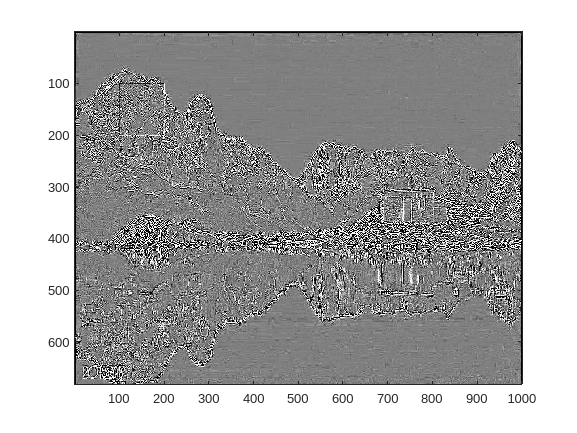

masque = -[1 1 1 ; 1 -8 1 ; 1 1 1]; 
W = 1; % pour avoir toutes les dynamiques
NL = size(ndg,1); % nb de lignes
NC = size(ndg,2); % nb de colonnes
offset = 128;
conv = zeros(NL,NC);

for L=2:NL-1
    for C=2:NC-1
        conv(L,C) = offset + sum(sum(masque.*ndg(L-1:L+1,C-1:C+1))) / W;
        % offset pour shift du 0 au milieu de l'échelle pour pas avoir des valeurs négatives
    end
end

figure(14)
image(conv);
colormap(gris) 

Le niveau de gris au niveau d'une très basse fréquence correspond au 0. Tout ce qui s'affiche plus clair sont des valeurs positives, plus sombre sont des valeurs négatives. Quand y'a des contours, on voit donc les hautes fréquences qui ont des valeurs importantes.

Filtre passe-bas --> flou pcq on supprime des hautes fréquences.

Donc si on ajoute des hautes fréquences (qui sont propres à l'image) est-ce qu'on va améliorer sa netteté?

## Ajout de hautes fréquences

Filtre avec que des zeros et un 1 au milieu est un filtre qui fait rien du tout. On peut construire un filtre qui fait du réhaussement, combinaison entre un filtre qui fait rien et un filtre qui sort les hautes fréquences.

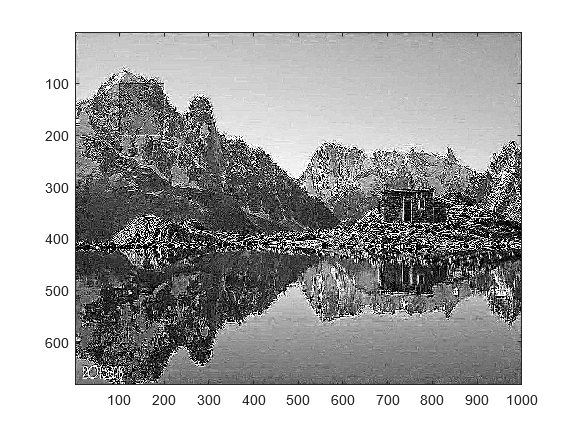

masque = -[1 1 1 ; 1 -9 1 ; 1 1 1];
offset = 0;
W = 1;
conv = zeros(NL,NC);

for L=2:NL-1
    for C=2:NC-1
        conv(L,C) = offset + sum(sum(masque.*ndg(L-1:L+1,C-1:C+1))) / W;
        % offset pour shift du 0 au milieu de l'échelle pour pas avoir des valeurs négatives
    end
end

figure(15)
image(conv);
colormap(gris) 

Mais ça altère beaucoup l'image, donc pour avoir un résultat meilleur faut le faire à la main. On récupère les valeurs de convolution, mais on altère les valeurs de hautes fréquences grâce au coef de pondération W.

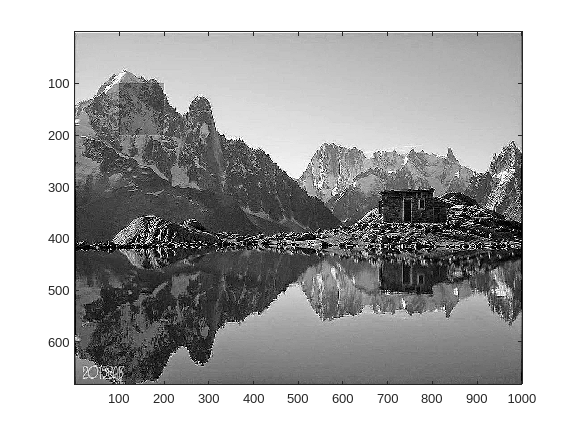

masque = -[1 1 1 ; 1 -8 1 ; 1 1 1];
offset = 0;
W = 5; % augmenter W pour diminuer le bruit et inversement
conv = zeros(NL,NC);

for L=2:NL-1
    for C=2:NC-1
        conv(L,C) = offset + sum(sum(masque.*ndg(L-1:L+1,C-1:C+1))) / W;
        % offset pour shift du 0 au milieu de l'échelle pour pas avoir des valeurs négatives
    end
end

figure(15)
image(conv + ndg); % on ajoute à la main les hautes fréquences atténuées à ndg (l'image)
colormap(gris) 

Si on considère que les images sont des surfaces, on peut résonner de façon fréquentielle.

## Masque de Sobel

Masque qui permet de détecter les contours verticaux ou horizontaux dépendant de son orientation. Ca donnera des valeurs importantes pour les pixels qui sont sur des contours verticaux et 0 sinon.

Pour les contours, on a des valeurs très négatives puis des valeurse très positives pour bien voir la différence

% sobel = [ -1 -2 1 ; 0 0 0 ; 1 2 1 ]'; % detection des contours horizontaux (transposée pour verticaux)
% sobelDiag = [ -2 -1 0 ; -1 0 1 ; 0 1 2 ];
 sobel = [ 0 1 0 ; 1 -4 1 ; 0 1 0 ];
offset = 128;
W = 1; % augmenter W pour diminuer le bruit et inversement
conv = zeros(NL,NC);

for L=2:NL-1
    for C=2:NC-1
        conv(L,C) = offset + sum(sum(masque.*ndg(L-1:L+1,C-1:C+1))) / W;
        % offset pour shift du 0 au milieu de l'échelle pour pas avoir des valeurs négatives
    end
end

figure(16)
image(conv);
colormap(gris) 

## Filtres non linéraires

On peut faire un filtre médian, qui a le même comportement qu'un filtre par convolution.

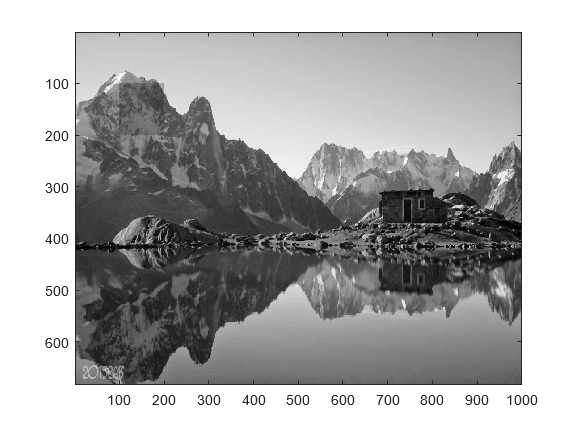

sobel = [ 0 1 0 ; 1 -4 1 ; 0 1 0 ];
med = zeros(NL,NC);

for L=2:NL-1
    for C=2:NC-1
        med(L,C) = median(ndg(L-1:L+1,C-1:C+1),'all');
        % offset pour shift du 0 au milieu de l'échelle pour pas avoir des valeurs négatives
    end
end

figure(17)
image(med);
colormap(gris) 

On obtient un flou médian.

## Dilatation et érosion

On utilise un élément structurant. C'est pas un carré though donc un peu plus compliqué algorithmiquement. Il définit une origine. On définit des zones de blanc et de noir et on fait un test d'intersection entre les zones et l'élément structurant. Dilatation on test juste l'appartenance d'un pixel allumé dans l'élément, alors que érosion on test l'appartenance dans l'élément complètement. On peut faire disparaitre des formes noires (un pixel noir au milieu d'une zone blanche - dilation sur des zones blanches) CF WIKIPEDIA

On prend la valeur max des pixels à l'intérieur du masque (max dans le masque), il suffit qu'il y ait intersection avec un point  blanc pour que ce point blanc prenne la valeur du max. Pour l'érosion, on travaillle avec la valeur du min, et s'il y a un point noir dans une zone blanche, il prendra la valeur du min. 

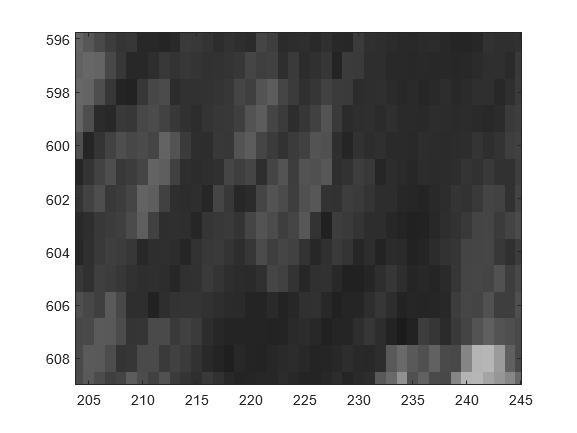

% dilatation
masque = [ 0 0 1 ; 0 1 0 ; 1 0 0 ];
dilat = zeros(NL,NC);

for L=2:NL-1
    for C=2:NC-1
        dilat(L,C) = max(max(masque.*ndg(L-1:L+1,C-1:C+1)));
        % offset pour shift du 0 au milieu de l'échelle pour pas avoir des valeurs négatives
    end
end

figure(18)
image(dilat);
colormap(gris) 

Ca donne des carrés qui grossissent (dilatés) si masque [ 1 1 1 ; 1 1 1 ; 1 1 1 ]

Sinon, ca donne des petites croix avec le masque [ 0 1 0 ; 1 1 1 ; 0 1 0 ] // ou des petits traits (diagonales) avec [ 0 0 1 ; 0 1 0 ; 1 0 0 ].

## Fonctions

On va traiter les luminosités (histogramme) avec la fonction histo(ndg)

function h = histo(ndg)

h = zeros(1,256); % 256 niveaux de gris, on remplit en fonction des pixels de l'image

NL = size(ndg,1); % nb de lignes
NC = size(ndg,2); % nb de colonnes

for L = 1:NL
    for C = 1:NC
        h(ndg(L,C) + 1) = h(ndg(L,C) + 1) + 1;
    end
end

end

nombre de pixels qui ont un niveau de gris inférieur ou égal à la valeur courante (une valeur donnée) --> histogramme cumulé

function hcum = histocum(ndg)
hcum = zeros(1,256); % 256 niveaux de gris, on remplit en fonction des pixels de l'image

h = histo(ndg);
hcum(1) = h(1);

for n = 2:256
    hcum(n) = hcum(n-1)+h(n); % integrale de la precedente
end

end